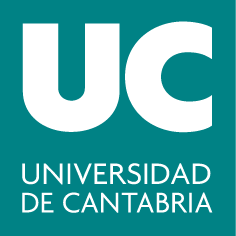

***Grados en Ingeniería de los Recursos Energéticos y de los Recursos Mineros***

**Cálculo**

# **5. Cálculo integral**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Cálculo de integrales indefinidas

La función` int` de MATLAB permite calcular directamente integrales indefinidas en las que el integrando sea una  expresión simbólica: 

**Ejemplo**: Calculamos las siguientes integrales:


$$$\int \cos^{2} \left(\frac{x}{2}\right) dx$ $$


syms x real   % defino 'x' como variable simbolica real
f1(x) = cos(x/2)^2;  % funcion a integrar
F1(x) = int(f1)  % primitiva (sin constante de integracion)

**Ejercicio:**$ $\int \frac{1}{1+\sqrt{x}} dx$  $

Esta integral se puede resolver utilizando el cambio de variable $$t=\sqrt{x}$$

% escribe aquí el código




Solución:

f2(x) = 1/(1+sqrt(x));  % funcion a integrar
F2(x) = int(f2)  % primitiva (sin constante de integracion)

**Ejercicio:** $ $\int x e^x dx$$

Esta integral se resuelve fácilmente por partes ($$u=x$, $dv=e^x dx$$)

% escribe aquí el código




Solución:

f3(x) = x*exp(x);  % funcion a integrar
F3(x) = int(f3)  % primitiva (sin constante de integracion)

Podemos comprobar fácilmente que las primitivas que hemos obtenido son correctas. Para ello, bastaría con ver que su derivada coincide con el integrando:

simplify(diff(F1) - f1)  % F1 es una primitiva correcta
simplify(diff(F2) - f2)  % F2 es una primitiva correcta
simplify(diff(F3) - f3)  % F3 es una primitiva correcta

Aquí, hemos empleado el comando `simplify` que se utiliza para simplificar expresiones simbólicas, es decir, reducirlas a una forma más compacta o sencilla, eliminando términos redundantes o combinando términos semejantes. 

Evidentemente, si sumamos cualquier constante de integración a las primitivas que hemos obtenido, éstas seguirán siendo igual de válidas:

simplify(diff(F1 + 5) - f1)  % F1+5 es una primitiva correcta
simplify(diff(F2 - pi) - f2)  % F2-pi es una primitiva correcta
simplify(diff(F3 + sqrt(2)) - f3)  % F3+sqrt(2) es una primitiva correcta

### Cálculo de integrales definidas

El comando` int` también permite calcular integrales definidas. Para ello, sólo tendremos que especificar mediante argumentos de entrada los límites del intervalo de integración de interés:

**Ejercicio:** Calcula las siguientes integrales (continuación del ejemplo anterior):


$$ $\int_{-2}^{\frac{\pi}{2}} \cos^{2} \left(\frac{x}{2}\right) dx$$$


% escribe aquí el código




Solución:

f1_def = double(int(f1, -2, pi/2))  % valor (numerico) de la integral definida 


$$ $\int_{0}^{1} \frac{1}{1+\sqrt{x}} dx$ $$


% escribe aquí el código




Solución:

f2_def = double(int(f2, 0, 1))  % valor (numerico) de la integral definida


$$$\int_{0}^{e} x e^x dx$$$


% escribe aquí el código




Solución:

f3_def = double(int(f3, 0, exp(1)))  % valor (numerico) de la integral definida

#### Regla de Barrow

Podríamos recurrir a la regla de Barrow


$$	$$\int_{a}^{b} f(x)dx = F(b)- F(a)$$$$


 para comprobar que los resultados que acabamos de obtener son correctos:

f1_def_rb = double(F1(pi/2) - F1(-2)) 
f2_def_rb = double(F2(1) - F2(0)) 
f3_def_rb = double(F3(exp(1)) - F3(0))  % comprobacion: regla de Barrow

#### Áreas

 Como sabemos, el valor de una integral definida se corresponde con el área encerrada entre la curva definida por el integrando y el eje $$X$$, confinada lateralmente por los extremos del intervalo de integración (hay que tener en cuenta que las porciones que queden por debajo del eje $$X$$ serían negativas).

La función `area `de MATLAB permite** dibujar **dicho área, por lo que resulta útil en la interpretación gráfica de los resultados obtenidos al calcular integrales definidas. Ten en cuenta que esta función sólo acepta valores numéricos (nunca expresiones simbólicas) como argumentos de entrada.

**Ejemplo:** Representamos gráficamente la función $$f(x)= x^2 + 1$$ en el intervalo$ $[1,3]$ $y sombrea, en rojo, la región del plano cuya área viene dada por $$I = \int_{1}^{3} \left( x^2+1 \right) dx$$:

1. Creamos dos vectores: `x`, para abscicas, y calculamos valores de la función $f(x)$ en esos puntos, $y = f(x)$:

clearvars
x = linspace(1, 3);  % secuencia de 100 numeros (equiespaciados) entre el 1 y el 3
y = x.^2+1;  % valor (numerico) de la funcion 'f' en esos 100 puntos

2. Representamos gráficamente la función:

plot(x,y,'k','LineWidth',2)
grid on
xlabel('x')
ylabel('y')

3. Sombreamos el area encerrada entre 'f' y el eje 'X' en rojo:

hold on
area(x, y, 'FaceColor','r')  % (por defecto se utiliza el color azul) 
title('f(x)=x^2+1')
hold off

Cuando se trabaja con intervalos de integración simétricos respecto al origen, es decir, centrados en 0 y con la misma extensión hacia la derecha y hacia la izquierda, resulta especialmente útil analizar la paridad del integrando. Esto se debe a que, si la función que se está integrando (el integrando) es par o impar, se pueden simplificar considerablemente los cálculos:

- **Funciones pares (**$f(x) = f(-x)$**):** La integral en un intervalo simétrico se puede calcular simplemente como el doble de la integral desde 0 hasta el extremo positivo del intervalo.

- **Funciones impares (**$f(x) =- f(-x)$**):** La integral en un intervalo simétrico alrededor de 0 es siempre 0, debido a la cancelación de las áreas bajo la curva a la derecha y a la izquierda del origen.

**Ejemplo:** Calculamos 

- $$\int_{\frac{-\pi}{2}}^{\frac{\pi}{2}} sen^{2}(x) \cos(x) dx$$ (¿el integrando es par o impar?)

1. Definimos  la función y representamos el área:

clearvars
syms x real  
f(x) = sin(x)^2*cos(x);  % integrando
X = linspace(-pi/2,pi/2);
Y = double(f(X));
area(X,Y,'FaceAlpha',0.5)
grid on

Función parece ser par, comprobamos:

f1 = subs(f,x,-x) % calculamos f(-x)

Podemos ver que $f(-x) = f(x)$, es decir, el integrando es par. 

3. Como el integrando es par, podemos calcular la integral así:

I = 2*int(f, 0, pi/2) 

4. Comprobamos que es exactamente $$I = \int_{\frac{-\pi}{2}}^{\frac{\pi}{2}} sen^{2}(x) \cos(x) dx$$:

I = int(f, -pi/2, pi/2) 

**Ejercicio:** Calcula $$\int_{-2}^{2} x(x^2 + 1)^3 dx$ $ usando las simetrias. 

% escribe aquí el código




Solución:

f(x) = x*(x^2+1)^3;  % integrando
% opción 1:
I=int(f, -2, 2)  % calculo la integral definida pedida
% opción 2:
f1 = subs(f,x,-x) % calculamos f(-x) que es igual a -f(x), entonces, f(x) es impar, I = 0.
I = 0;
% visualizacion %
x = linspace(-2, 2);  % secuencia de 100 numeros (equiespaciados) entre -2 y 2
y = double(f(x));  % valores (numericos) que toma el integrando para esa secuencia de 'x'
area(x, y)   % area encerrada entre la grafica definida por el integrando y el eje X
grid on

#### Sumas de Riemann

La función` rsums` permite aproximar el valor de una integral definida mediante sumas de Riemann. Para ello, se abre una ventana gráfica desde la cual es posible ajustar el número de rectángulos considerados en la aproximación (el área correspondiente aparecerá en la parte superior de la figura). Ten en cuenta que` rsums `requiere como entrada una función simbólica:

**Ejemplo:** Aproximamos el valor de$ $\int_{1}^{3} \left( x^2+1 \right) dx$$ mediante sumas de Riemann con 10, 20, 30 rectángulos. ¿Qué error porcentual (con respecto al valor exacto) se comete en cada una de estas aproximaciones?

clearvars
syms x real  % defino 'x' como variable simbolica
rsums(x^2+1, 1, 3)  % aproximacion de la integral pedida con 10 rectangulos (valor por defecto que usa 'rsums')

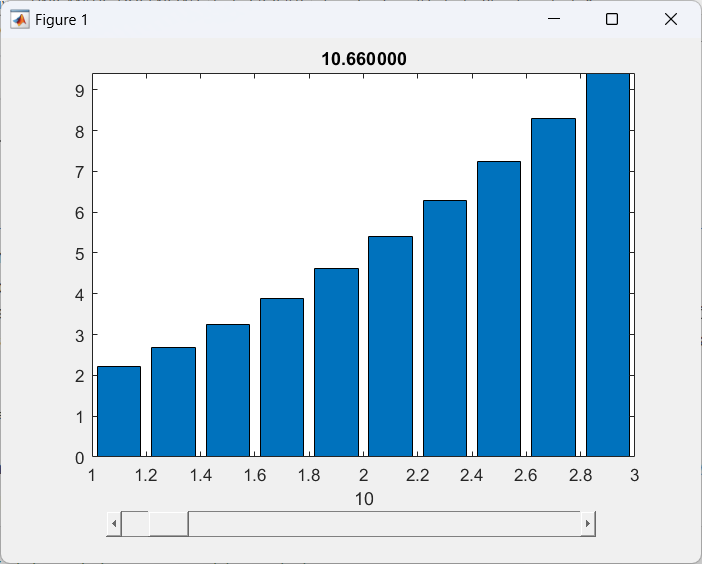

va10 = 10.66;  % valor aproximado de la integral pedida usando 10 rectangulos

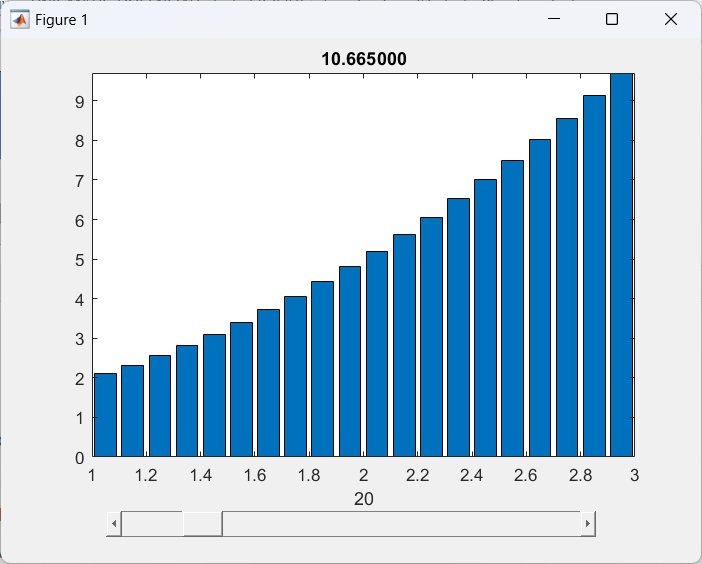

va20 = 10.665;  % valor aproximado de la integral pedida usando 20 rectangulos

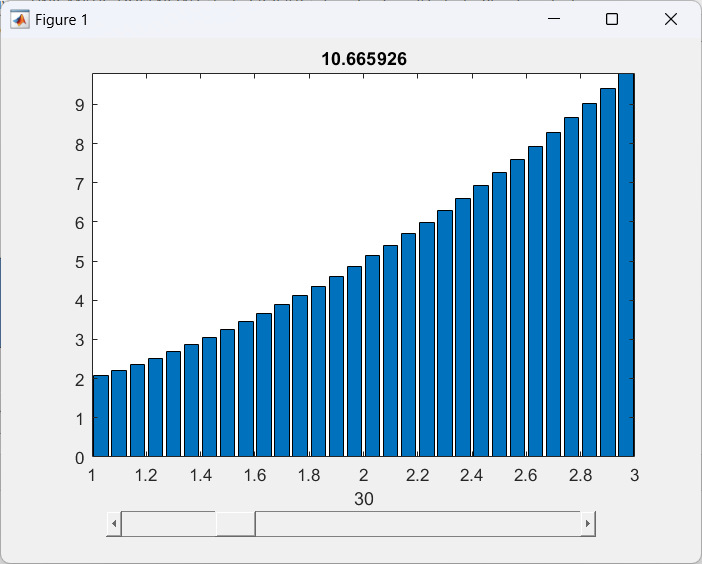

va30 = 10.665926;  % valor aproximado de la integral pedida usando 30 rectangulos

Calculamos el valor exacto y los errores:

ve = double(int(x^2+1, 1, 3));  % valor (numérico) exacto de la integral pedida
Errors = 100*abs(([va10 va20 va30] - ve) / ve)  % errores (en %) cometidos por las aproximaciones con 10, 20 y 30 rectangulos

Como se puede observar, la aproximación mediante sumas de Riemann mejora a medida que aumenta el número de rectángulos considerados.

### **Ejercicios propuestos**

1. Dada la función $$f(x)=\ln^2(x)$$, ¿cuánto valdría $$F(\sqrt{\pi})$$, siendo $$F$ $una primitiva de $$f$$ con constante de integración igual a $$5$$?

% escribe aquí el código




Solución:

soluciones(1)

2. Representa en una misma figura las funciones $$f(x)=(x-1)^2$$ y $$g(x)=\sqrt{\frac{\pi}{3}} x$$ y halla el área que queda encerrada entre ambas.

% escribe aquí el código





Solución:

soluciones(2)

3. ¿Qué error porcentual se comete al aproximar mediante sumas de Riemann con 5, 15 y 25 rectángulos la integral $$\int_{-1}^{\pi} e^x sen(2x) dx$$?	

% escribe aquí el código








Solución:

soluciones(3)

4. Comprueba, estudiando su paridad, que la integral  $$\int_{-1}^{1} \left( arctan(x)^3 - x \right)^5 dx=0$$ . A continuación, ratifica tus resultados gráficamente utilizando la función` area`.

% escribe aquí el código









Solución:

soluciones(4)

### Resumen

**Cálculo de integrales**

- [`int(f)`](https://es.mathworks.com/help/symbolic/sym.int.html)**:** Calcula la integral indefinida de una función simbólica. Retorna la primitiva de la función, excluyendo la constante de integración.

- [`int(f, a, b)`](https://es.mathworks.com/help/symbolic/sym.int.html)**:** Calcula la integral definida de la función simbólica `f` desde el límite inferior `a` hasta el límite superior `b`. Retorna el valor numérico de la integral definida.

- [`rsums(f,a,b)`](https://es.mathworks.com/help/symbolic/rsums.html)**:** Aproxima el valor de una integral definida usando sumas de Riemann. Permite ajustar el número de rectángulos en la aproximación y abre una ventana gráfica para visualizar la integración.

**Áreas**

- [`area(x,y)`](https://es.mathworks.com/help/matlab/ref/area.html)**:** **Dibuja** el área bajo la curva de una función sobre un intervalo específico. Acepta vectores numéricos para las coordenadas `x` e `y`, y sombrea el área encerrada entre la función y el eje `x`.

**Otras funciones útiles**

- [`simplify(expr)`](https://es.mathworks.com/help/symbolic/simplify.html)**:** Simplifica expresiones simbólicas, reduciéndolas a una forma más compacta o más sencilla, eliminando términos redundantes o combinando términos semejantes.

### Soluciones 

function [] = soluciones(n)
switch n
    case 1
        % Ejercicio 1:
        fprintf("Ejercicio 1:\n");
        syms x real
        f(x) = log(x)^2;
        C = 5;
        F(x) = int(f) + C % añadimos C = 5 (constante de integración)
        I = double(F(sqrt(pi)))
    case 2
        % Ejercicio 2:
        fprintf("Ejercicio 2:\n");
        close all
        syms x real
        f(x) = (x-1)^2;
        g(x) = sqrt(pi/3)*x;
        fplot(f,[0, 3],'r')
        hold on
        fplot(g,[0, 3],'b')
        legend('f(x)', 'g(x)');
        grid on
        hold off
        pc = sort(double(solve(f-g))); % puntos de corte
        A = int(g-f,pc(1),pc(2));
        fprintf('Puntos de corte: a = %f, b = %f\nÁrea: %f (u2)',pc(1),pc(2),A);
    case 3
        % Ejercicio 3:
        fprintf("Ejercicio 3:\n");
        syms x real
        f(x) = exp(x)*sin(2*x);
        a = -1; b = pi;
        ve = double(int(f,a,b));
        %rsums(f,a,b)
        va5 = -10.610531;
        va15 = -9.399999;
        va25 = -9.304313;
        Errors = 100*abs(([va5 va15 va25] - ve) / ve);
        fprintf('5 rectángulos:  Valor aprox = %f, Error = %.4f%%\n15 rectángulos: Valor aprox = %f,  Error = %.4f%%\n25 rectángulos: Valor aprox = %f,  Error = %.4f%%\n',va5,Errors(1),va15,Errors(2),va25,Errors(3));
    case 4
        % Ejercicio 4:
        fprintf("Ejercicio 4:\n");
        syms x real
        f(x) = (atan(x)^3-x)^5;
        % paridad:
        f1(x) = subs(f,x,-x);
        I = int(f,-1,1);
        fprintf("f(-x) = %s; -f(x) = %s, entonces f(x) es impar, I =0.\nCalculamos la integral: I = %f",char(f1), char(-f),I)
        x = linspace(-1,1);
        y = double(f(x));
        area(x,y,'FaceAlpha',0.5)
        grid on

end
end